# **Influenza Model**

### **Motivating Question:** *How long will the flu disease outbreak last?*

*This data will help health officials, researchers, and the general public about how the effects of the outbreak and how long we should expect the pandemic will last.*

%ModelMk1:
%Parameters: i_0 (infectious people), s_0 (susceptible people), r_0
%(recovered people), beta (infection rate), and gamma (recovery rate)
%Precondition: There are i_0 = 2 infectious people, s_0 = 98 susceptible people, and
%r_0 = 0 recovered people. Beta = 1/90 and and gamma = 1/2
%Postcondition: There are the same number of people in the system at the
%end of the simulation as there were at the beginning. There are 0 people
%in the i_0 stock, signaling the end of the outbreak


% Initial state of model
% A population of 100 persons, 98 susceptible and 2 infectious people
%{
i_0 = 2;
s_0 = 100 - i_0;
r_0 = 0;
Total = i_0 + s_0 + r_0;

beta = 1 / 90; %Infection rate
gamma = 1 / 2; %Recovery rate

[S_fit, I_fit, R_fit, W_fit] = sir_simulate(s_0, i_0, r_0, beta, gamma, 30); %Runs the actual simulation, storing the results in vectors

plotting; %Plots the results of the model
%}

%{
Verification:
Facts: The # of people in each stock, i_0, s_0, and r_0, total to 100. The
total number of people at the end of the simulation still remains the same.
%}

%Interpretation - ModelMk1:
%Fill in here
%Need to try different total values and different i_0 values



%ModelMk2:
%Parameters: i_0 (infectious people), s_0 (susceptible people), r_0
%(recovered people), beta (infection rate), and gamma (recovery rate)
%Precondition: There are i_0 = 2 infectious people, s_0 = 98 susceptible people, and
%r_0 = 0 recovered people. Beta = 1/90 and and gamma = 1/2
%Postcondition: There are the same number of people in the system at the
%end of the simulation as there were at the beginning. There are 0 people
%in the i_0 stock, signaling the end of the outbreak

i0_sweep = 2:1:10; %Defines the sweep for i_0
s0_sweep = 98:100:998

s0_sweep =     98   198   298   398   498   598   698   798   898   998


i_0 = 2;
s_0 = 100 - i_0;
r_0 = 0;
Total = i_0 + s_0 + r_0; %Total # of people in the system

clf
hold on
for i_0 = i0_sweep
    outbreak_sweep;
    plot(s0_sweep, s0_end)
end

hold off

xlabel('i0\_frac')
ylabel('Stuff')


lgd = legend(string(s0_sweep)); 

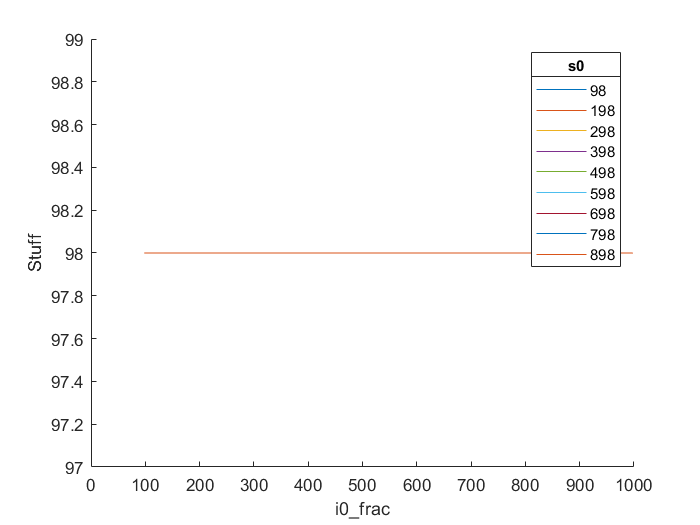

lgd.Title.String = 's0';     
lgd.Location = 'northeast';   